% Question 1
C = 37;
F = (9*C)/5 +32

   98.6000



% Question 2
N = [1 2 3 4 5];
a = 2.*N

a =      2     4     6     8    10


b = N./2

b =     0.5000    1.0000    1.5000    2.0000    2.5000


c = 1./N

c =     1.0000    0.5000    0.3333    0.2500    0.2000


d=1./(N.^2)

d =     1.0000    0.2500    0.1111    0.0625    0.0400


%Question 3
sum = 0;
for i = 1:1000
    sum = sum + 1/i*(-1)^(i-1);
end
sum

sum = 0.6926

log(2)%pretty close

ans = 0.6931

%Quesion 4
x = 1;
for i = 1:100
    if(rem(i+1,10)==0)
        x = (10*x)/i
    else
        x = (10*x)/i;
    end
end

x = 2.7557e+03

x = 41.1032

x = 0.0038

x = 1.2256e-08

x = 3.2879e-15

x = 1.2018e-22

x = 8.3482e-31

x = 1.3972e-39

x = 6.7308e-49

x = 1.0715e-58

x = 1.0715e-58

%Question 5
syms x;
y = piecewise(sin(x)>0, sin(x), 0)

$$y = \left\{ \begin{array}{cl} \sin\left(x\right) & \text{ if }0<\sin\left(x\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

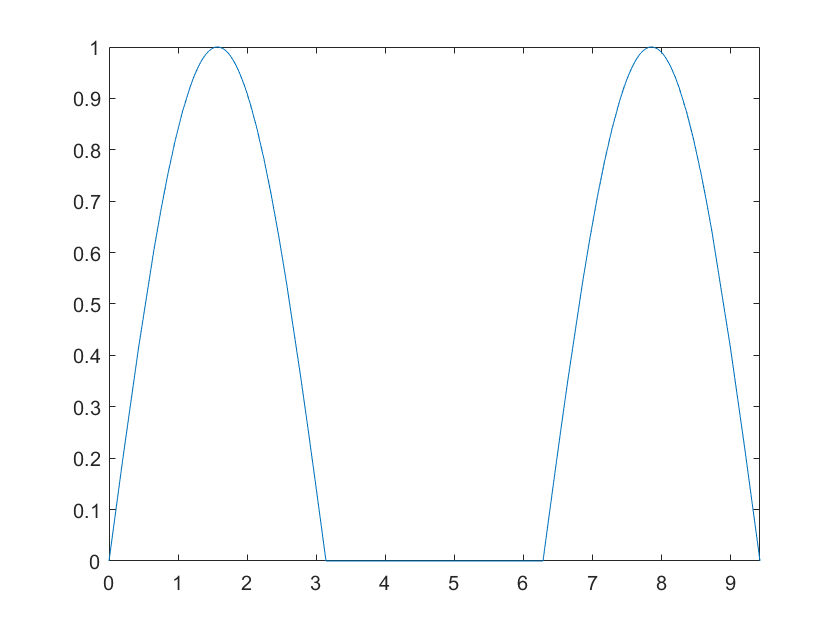

fplot(y,[0, 3*pi])

%Question 6
roll = ceil(6*rand(1, 20));
prob = nnz(roll==6)/20

prob = 0.1000


roll = ceil(6*rand(1, 1000));
prob = nnz(roll==6)/1000

prob = 0.1820

1/6

ans = 0.1667

%Question 7
b = [1:7; 9:-2:-3; 2.^[2:8]]

b =      1     2     3     4     5     6     7
     9     7     5     3     1    -1    -3
     4     8    16    32    64   128   256


a = b(:,5)+b(:,7)

a =     12
    -2
   320


B = b(3,:)

B =      4     8    16    32    64   128   256


c=b;
temp = c(2,:);
c(2,:)=c(3,:);
c(3,:) = temp;
c

c =      1     2     3     4     5     6     7
     4     8    16    32    64   128   256
     9     7     5     3     1    -1    -3


%Question 8
v1 = [1 2 3 4 5]

v1 =      1     2     3     4     5


v2 = [1;1;1;1;1]

v2 =      1
     1
     1
     1
     1


a = v1.*[1;1;1;1;1]

a =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5


b = transpose(v2).*transpose(v1-1)

b =      0     0     0     0     0
     1     1     1     1     1
     2     2     2     2     2
     3     3     3     3     3
     4     4     4     4     4


%Question 9
vx0 = 50:0.5:100; 
vy0 = 100:200;

misses = transpose([vx0;vy0; cannonBall(vx0, vy0)])

misses =    50.0000  100.0000  893.4989
   50.5000  101.0000  882.4144
   51.0000  102.0000  871.3325
   51.5000  103.0000  860.2530
   52.0000  104.0000  849.1762
   52.5000  105.0000  838.1022
   53.0000  106.0000  827.0310
   53.5000  107.0000  815.9628
   54.0000  108.0000  804.8977
   54.5000  109.0000  793.8358



[x,y] = meshgrid(50:0.5:100,100:200)

x =    50.0000   50.5000   51.0000   51.5000   52.0000   52.5000   53.0000   53.5000   54.0000   54.5000   55.0000   55.5000   56.0000   56.5000   57.0000   57.5000   58.0000   58.5000   59.0000   59.5000   60.0000   60.5000   61.0000   61.5000   62.0000   62.5000   63.0000   63.5000   64.0000   64.5000   65.0000   65.5000   66.0000   66.5000   67.0000   67.5000   68.0000   68.5000   69.0000   69.5000   70.0000   70.5000   71.0000   71.5000   72.0000   72.5000   73.0000   73.5000   74.0000   74.5000
   50.0000   50.5000   51.0000   51.5000   52.0000   52.5000   53.0000   53.5000   54.0000   54.5000   55.0000   55.5000   56.0000   56.5000   57.0000   57.5000   58.0000   58.5000   59.0000   59.5000   60.0000   60.5000   61.0000   61.5000   62.0000   62.5000   63.0000   63.5000   64.0000   64.5000   65.0000   65.5000   66.0000   66.5000   67.0000   67.5000   68.0000   68.5000   69.0000   69.5000   70.0000   70.5000   71.0000   71.5000   72.0000   72.5000   73.0000   73.5000   74.0000   74

y =    100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101
   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102
   103   103   103   103   103   103   103   103   103   103   103   103   103   103   103   

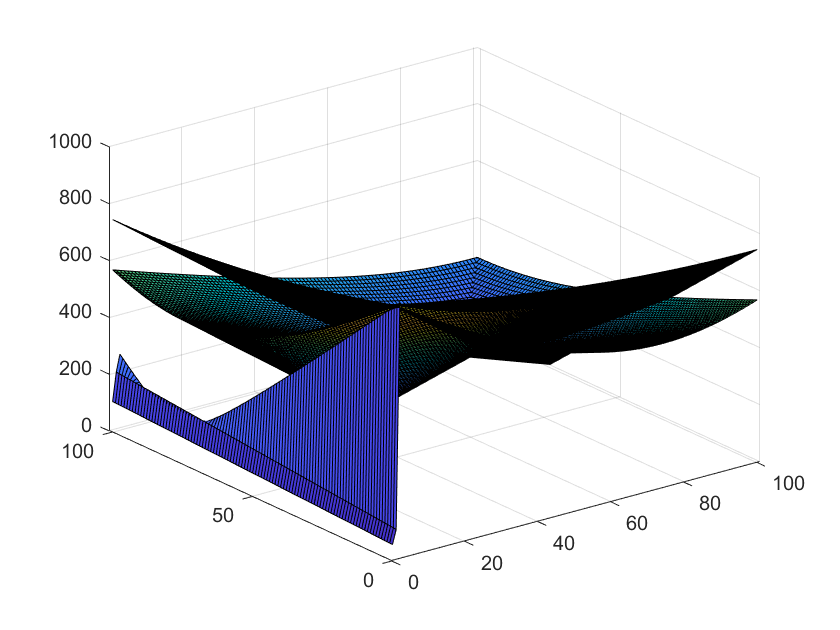

miss = cannonBall(x, y);
surf(miss)

[value, index] = min(misses(:,3))

value = 116.0829

index = 80

[row, col] = ind2sub(size(misses), index)

row = 80

col = 1

%Question 9 function

%a

function [dMiss] = cannonBall(vx0, vy0)
t = 10;
xT = 1000;
yT = 1250;
g = 9.81;

xMiss = vx0.*t -xT;
yMiss = vy0.*t-0.5.*g.*t.^2-yT;
dMiss = sqrt(yMiss.^2+xMiss.^2);
end


